# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

## Problem 1 

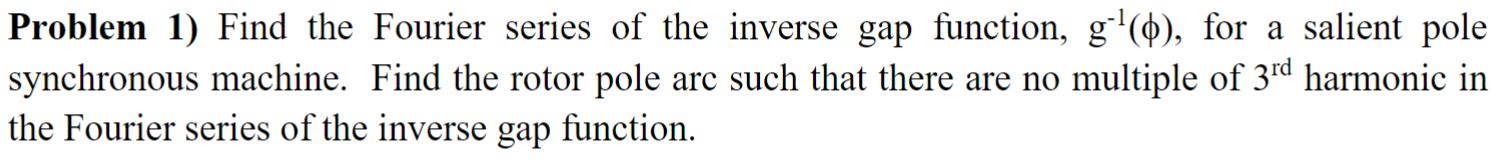

Express gap length as a function of the angle Φ.

clearvars 
clc 

syms g_min g_max     positive real
syms alpha           positive real 
syms phi                      real 
syms g_phi(phi)
syms theta_r theta 

assume( (alpha > 0) & (alpha <= deg2rad(180)) )

T = 2*pi;
POLEARC = deg2rad(90);
THETA_R = deg2rad(45);

poleArc = alpha;
midArc = T/2 - poleArc;

rotor_profile_theta = [poleArc/2 midArc poleArc midArc poleArc/2];
rotor_profile_turning_theta_r = theta_r + cumsum(rotor_profile_theta)

$$rotor\_profile\_turning\_theta\_r = \left(\begin{array}{ccccc} \frac{\alpha }{2}+\theta_{r} & \theta_{r}-\frac{\alpha }{2}+\pi & \frac{\alpha }{2}+\theta_{r}+\pi & \theta_{r}-\frac{\alpha }{2}+2\,\pi & \theta_{r}+2\,\pi \end{array}\right)$$

% disp(rotor_profile_turning_theta_r)
% The location of a point of symmetry on one of the two-pole faces
% is now aligned with the reference position for the φ
% which is selected as the (magnetic) axis of phase A
phi_ref = 0;
rotor_profile_turning_phi = subs(rotor_profile_turning_theta_r, theta_r, -deg2rad(phi_ref))

$$rotor\_profile\_turning\_phi = \left(\begin{array}{ccccc} \frac{\alpha }{2} & \pi -\frac{\alpha }{2} & \frac{\alpha }{2}+\pi & 2\,\pi -\frac{\alpha }{2} & 2\,\pi \end{array}\right)$$

% add phi_ref to rotor_profile_turning_phi for better consistency  
rotor_profile_turning_phi = [phi_ref, rotor_profile_turning_phi]

$$rotor\_profile\_turning\_phi = \left(\begin{array}{cccccc} 0 & \frac{\alpha }{2} & \pi -\frac{\alpha }{2} & \frac{\alpha }{2}+\pi & 2\,\pi -\frac{\alpha }{2} & 2\,\pi \end{array}\right)$$

gap_profile = [g_min, g_max, g_min, g_max, g_min];

firstPhi = rotor_profile_turning_phi(1);
secondPhi = rotor_profile_turning_phi(2);

firstGap = gap_profile(1);

g_phi(phi) = piecewise(firstPhi <= phi < secondPhi, firstGap)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }2\,\varphi <\alpha \wedge 0\leq \varphi \end{array}\right.$$


for k = 2 : length(rotor_profile_turning_phi) - 1 

    thisPhi = rotor_profile_turning_phi(k);
    nextPhi = rotor_profile_turning_phi(k+1); 
    thisGap = gap_profile(k);

    % Both lower and upper boundaries for phi are 'closed' 
    % i.e. [lower boundary, upper boundary]
    % if k == length(rotor_profile_turning_phi) - 1 
    %     g_phi(phi) = piecewise( ...
    %         thisPhi <= phi <= nextPhi, thisGap, ...
    %         phi <= thisPhi, g_phi(phi) ...
    %     ); 
    % end 

    % Only lower boundary is closed 
    g_phi(phi) = piecewise( ...
        thisPhi <= phi < nextPhi, thisGap, ...
        phi <= thisPhi, g_phi(phi) ...
    ); 
end  

g_phi(phi) = simplify(g_phi)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <2\,\pi \wedge 4\,\pi \leq \alpha +2\,\varphi \\ g_{\max} & \text{ if }\frac{\alpha }{2}+\pi \leq \varphi \wedge \alpha +2\,\varphi <4\,\pi \\ g_{\min} & \text{ if }\alpha +2\,\varphi \in \left[2\,\pi ,4\,\pi \right]\wedge 2\,\varphi <\alpha +2\,\pi \\ g_{\max} & \text{ if }\alpha \leq 2\,\varphi \wedge \alpha +2\,\varphi <2\,\pi \\ g_{\min} & \text{ if }2\,\varphi <\alpha \wedge 0\leq \varphi \end{array}\right.$$

vars = [poleArc g_min g_max theta_r];
VALS = [POLEARC 0.5   0.8   THETA_R];

% figure 
% fplot(subs(g_phi, vars, VALS), [0 2*T])
% hold on 
% ylim([0 1])
% grid on 
% ax = gca;
% S = sym(ax.XLim(1):pi/4:ax.XLim(2));
% ax.XTick = double(S);
% ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
g_phi_inv = 1 / g_phi

$$g\_phi\_inv(phi) = \left\{ \begin{array}{cl} \frac{1}{g_{\min}} & \text{ if }\varphi <2\,\pi \wedge 4\,\pi \leq \alpha +2\,\varphi \\ \frac{1}{g_{\max}} & \text{ if }\frac{\alpha }{2}+\pi \leq \varphi \wedge \alpha +2\,\varphi <4\,\pi \\ \frac{1}{g_{\min}} & \text{ if }\alpha +2\,\varphi \in \left[2\,\pi ,4\,\pi \right]\wedge 2\,\varphi <\alpha +2\,\pi \\ \frac{1}{g_{\max}} & \text{ if }\alpha \leq 2\,\varphi \wedge \alpha +2\,\varphi <2\,\pi \\ \frac{1}{g_{\min}} & \text{ if }2\,\varphi <\alpha \wedge 0\leq \varphi \end{array}\right.$$


% figure 
% fplot(subs(g_phi, vars, VALS), [0 2*T], ...
%     "DisplayName", "Gap Function", ...
%     "LineWidth", 1.2)
% hold on 
% fplot(subs(g_phi_inv, vars, VALS), [0 2*T], ...
%     "DisplayName", "Inverse Gap Function", ...
%     "LineWidth", 1.2)
% hold off 
% ylim([0 2.5])
% grid on 
% legend 
% 
% ax = gca;
% S = sym(ax.XLim(1):pi/4:ax.XLim(2));
% ax.XTick = double(S);
% ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
g_phi_inv_ext(phi) = piecewise( ...
    -2*T <= phi < -T, g_phi_inv(phi+2*T), ...
    -T <= phi < 0, g_phi_inv(phi+T), ...
    0 <= phi < T, g_phi_inv(phi), ...
    T <= phi <= 2*T, g_phi_inv(phi-T) ...
)

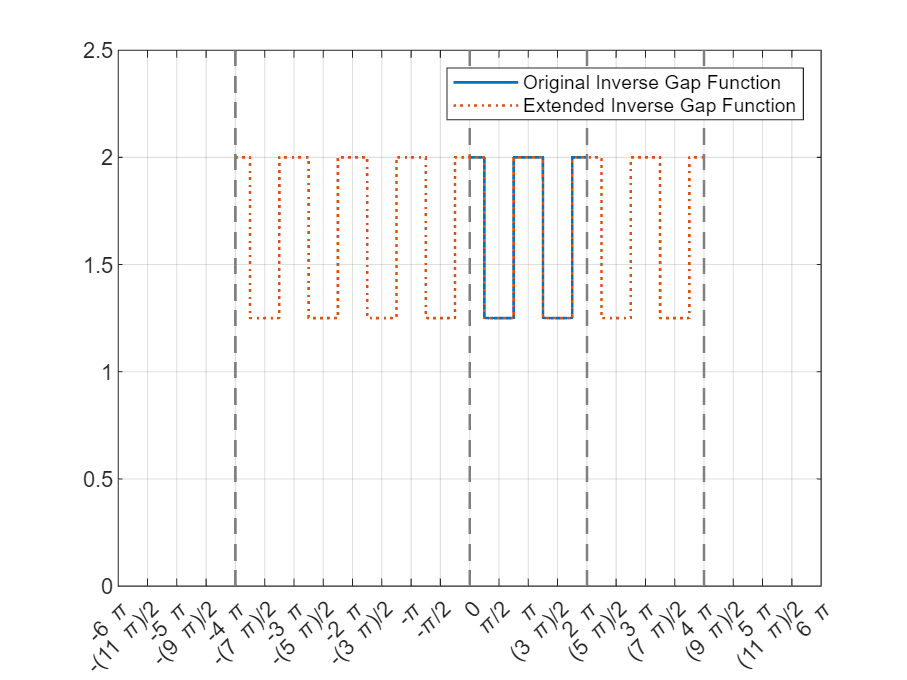


figure 
fplot(subs(g_phi_inv, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Original Inverse Gap Function", ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_inv_ext, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Extended Inverse Gap Function", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 
ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

digits(4)

a0 = vpa( (1/T) * int( subs(g_phi_inv, theta_r, THETA_R), phi, [0 T], ...
    'IgnoreSpecialCases', true) )

$$a0 = \frac{0.3183\,\alpha }{g_{\min}}-\frac{0.3183\,\left(\alpha -3.142\right)}{g_{\max}}$$

syms n 

an = (2/T) * int( subs(g_phi_inv, theta_r, THETA_R) * cos(n * phi), phi, [0 T]);
bn = (2/T) * int( subs(g_phi_inv, theta_r, THETA_R) * sin(n * phi), phi, [0 T]);

orderOfHarmonics = 1:13;
an_13 = vpa( simplify(subs(an, n, orderOfHarmonics)) ) 

$$an\_13 = \left(\begin{array}{ccccccccccccc} 0 & -\frac{0.6366\,\sin\left(\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 & -\frac{0.3183\,\sin\left(2.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 & -\frac{0.2122\,\sin\left(3.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 & -\frac{0.1592\,\sin\left(4.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 & -\frac{0.1273\,\sin\left(5.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 & -\frac{0.1061\,\sin\left(6.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & 0 \end{array}\right)$$

bn_13 = vpa( simplify(subs(bn, n, orderOfHarmonics)) )

$$bn\_13 = \left(\begin{array}{ccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


g_phi_inv_even_fourier = a0 + ...
                    sum( an_13 .* cos(orderOfHarmonics .* phi) + ...
                         bn_13 .* sin(orderOfHarmonics .* phi) )

$$g\_phi\_inv\_even\_fourier = \frac{0.3183\,\alpha }{g_{\min}}-\frac{0.3183\,\left(\alpha -3.142\right)}{g_{\max}}-\frac{0.3183\,\cos\left(4\,\varphi \right)\,\sin\left(2.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}-\frac{0.1592\,\cos\left(8\,\varphi \right)\,\sin\left(4.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}-\frac{0.1273\,\cos\left(10\,\varphi \right)\,\sin\left(5.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}-\frac{0.2122\,\cos\left(6\,\varphi \right)\,\sin\left(3.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}-\frac{0.1061\,\cos\left(12\,\varphi \right)\,\sin\left(6.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}-\frac{0.6366\,\cos\left(2\,\varphi \right)\,\sin\left(\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}$$

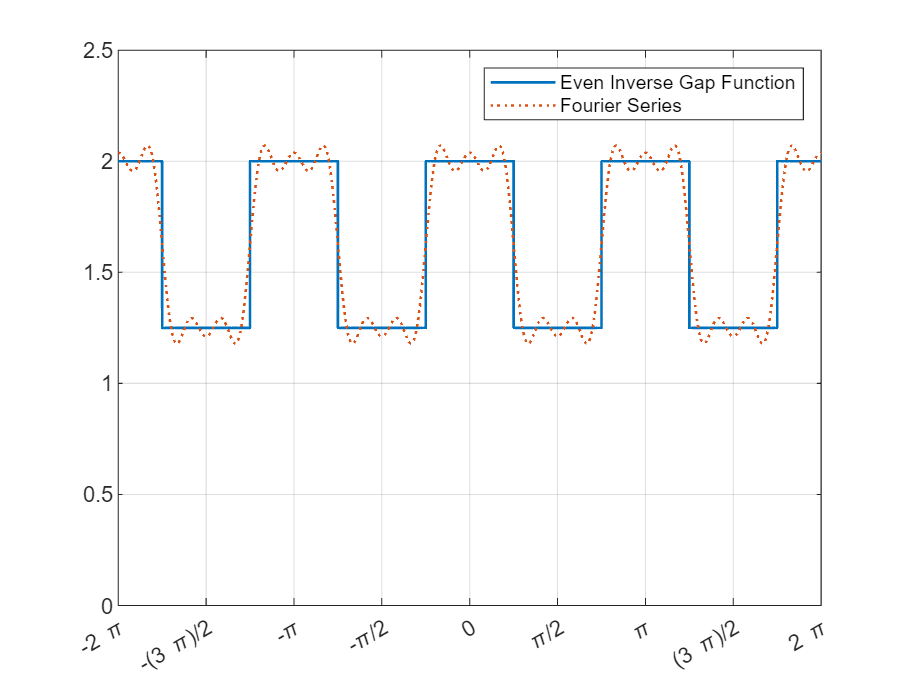


figure 
fplot(subs(g_phi_inv_ext, vars, VALS), [-T T], ...
      "DisplayName", "Even Inverse Gap Function", ...
      "LineWidth", 1.2)
hold on 
fplot(subs(g_phi_inv_even_fourier, vars, VALS), [-T T], ...
      "DisplayName", "Fourier Series", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 

ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Removal of Multiples of 3rd Harmonics in Fourier Series of Even Inverse Gap Function g(φ)^(-1)

terms = children(g_phi_inv_even_fourier);
multiplesOf3rd = find(mod(orderOfHarmonics,3)==0)

multiplesOf3rd =      3     6     9    12



% Initialize a symbolic zero to accumulate matching terms
matching_terms = [];

for i = 1:length(terms)
    if has(terms{i}, cos(multiplesOf3rd*phi))
        matching_terms = [matching_terms terms{i}]; % Accumulate matching terms
    end
end

disp(matching_terms);

$$\left(\begin{array}{cc} -\frac{0.2122\,\cos\left(6\,\varphi \right)\,\sin\left(3.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} & -\frac{0.1061\,\cos\left(12\,\varphi \right)\,\sin\left(6.0\,\alpha \right)\,\left(g_{\min}-1.0\,g_{\max}\right)}{g_{\min}\,g_{\max}} \end{array}\right)$$

It is clear that when $\alpha =\frac{m\pi }{3}$ where m is any positive integer, both $\cos \left(6\,\phi \right)$ and $\cos \left(12\,\phi \right)$ are eliminated as both $\sin \left(3.0\,\alpha \right)$ and $\sin \left(6.0\,\alpha \right)$ are zero.